# Track Monitor Class

The track monitor class is the main class that does the analysis for any flight before done during the simulation. There are a couple of main functions that the track monitor class performs. 

## Receiving Information From ATOC

The first this that the track monitor class has to do is receive the information of the ATOC class, which gathered the inforamtion from the simulation step. There are a couple of parameters that are needed: telemetry, sensory, and reservarion data specific to that simulation step. The code segment below shows the structures of the telemetry, sensory and reserveration that are being passed in. 

% Telemetry/Radar Data Structure
tnew = table();
tnew.ID = "";
tnew.pos = zeros(1, 3);
tnew.speed = zeros(1,3);
tnew.time = 0;
radars = tnew;
telemetry = tnew;
disp(radars)

    ID        pos           speed       time
    __    ___________    ___________    ____

    ""    0    0    0    0    0    0     0  



disp(telemetry)

    ID        pos           speed       time
    __    ___________    ___________    ____

    ""    0    0    0    0    0    0     0  




lbsd = LBSD.genSampleLanes(10, 15);
res = lbsd.getReservations();
disp(res)

This information is passed in with every time step from the atoc. The track monitor will use this information to analyze flights, which leads to the next section. 

## Tracking Flights

In order to be able to analyze flights, we first have to keep track of all of the flights and link all of the simulation steps to the correct uas. Therefore, the track monitor class takes advantage of keeping tracker objects of all of the uas' it comes across during the simulation. The main process of this is to cluster all of the data points from each simulation step, and use these groupings to accosicate it with a previous tracker object. 

### Clustering

Because each time step and potential rogue behaviors we can't determine the optimial number of clusters, so instead of using assignmnet based such as k-means or k-means++, we are using a heiracherial clustering algorithm. However, to keep the running time down, we are using a approximation of heiracherial clustering called db-scan. All of our error rates from machinary to report positions is in gausian noise, we used three standard deviation from the center of a group of items for the range of items that can be clustered together. This range that we are accepting are 3 meters from the center to be considered within the group. Then once the groups are clustering, we look at each individual groups and see if there is an active tracker object predicted position that is slightly off from the reported cluster.

### Find Associated Tracker

Once the clustering is done, it is time to find an associated tracker. If the reported clusters center is within a certain distance from the reported tracker's distance there is a higher probability that this tracker is associated with this cluster. However, if there is no associated tracker, a new tracker is created and kept in the list. Now that we have talked about workings behind keeping track of the differing UAS, lets see the actual progress of the flights and tracking that the Track Monitor actually performs. 

#### Tracking UAS Through A Simulations

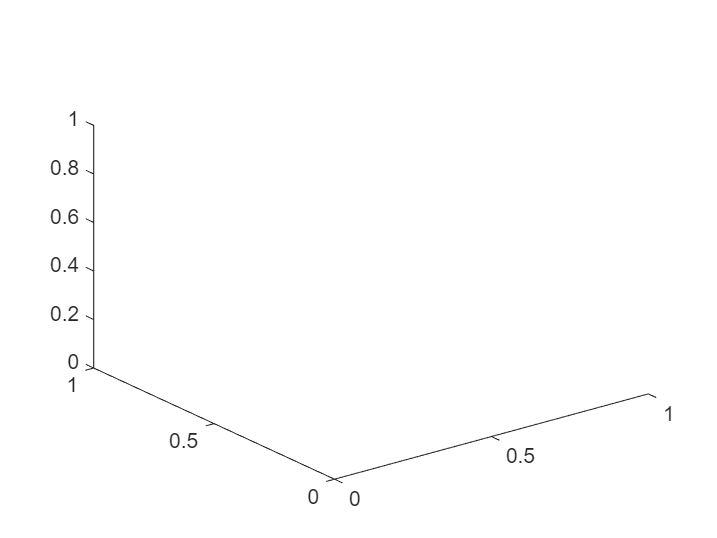

% Set up the a Single
rng(0);
monitor = TrackMonitor();
sim = Sim();
sim.lbsd = lbsd;
sim.initialize();
res = sim.lbsd.getReservations();
minTime = min(res.entry_time_s);
maxTime = max(res.exit_time_s);
num_steps = floor((maxTime - minTime)/sim.step_rate_hz) + 1000;
sim.atoc.time = minTime;
num_uas = length(sim.uas_list);

for steps = 1:num_steps
    tnew = table();
    tnew.ID = "";
    tnew.pos = zeros(1,3);
    tnew.speed = zeros(1,3);
    tnew.time = 0;
    index = 1;
    rindex = 1;
    telemetry = tnew;
    radars = tnew;
    for i = num_uas
        uas = sim.uas_list(i);
        uas_step = uas.stepTrajectory();
        if uas.active
            pos = uas.exec_traj;
            if ~isempty(pos)
                uas.gps.lon = pos(uas_step, 1);
                uas.gps.lat = pos(uas_step, 2);
                uas.gps.alt = pos(uas_step, 3);
                uas.gps.commit();
                traj = uas.exec_traj;
                set(uas.h, 'XData', traj(:,1), ...
                    'YData', traj(:,2), ...
                    'ZData', traj(:,3));
                telemetry{index, {'ID', 'pos', 'speed', 'time'}} = ...
                    [uas.id, [uas.gps.lon, uas.gps.lat, uas.gps.alt], ...
                    [uas.gps.vx, uas.gps.vy, uas.gps.vz], 0];
                index = index + 1;
            end
        end
    end
    sim.step(1);
    for index = 1:length(sim.radar_list)
        radar = sim.radar_list(index);
        for item = 1:size(radar.targets, 2)
            radars{rindex, {'ID', 'pos', 'speed', 'time'}}...
                = ["", zeros(1,3), zeros(1,3), 0];

            % Set up Table Entries
            pos = [radar.targets(item).x, ...
                radar.targets(item).y, radar.targets(item).z];
            speed = [radar.targets(item).s];

            % Input Items into the table
            radars.ID(rindex) = radar.ID;
            radars.pos(rindex, :) = pos;
            radars.speed(rindex, :) = speed;
            radars.time(rindex) = radar.time;
            rindex = rindex + 1;
        end
    end
    monitor.AnalyzeFlights(telemetry, radars, [],sim.tick_del_t);
end

% Plot Results
figure();
hold on;
for index = 1:num_uas
    uas = sim.uas_list(index);
    pos = uas.exec_traj;
    if(~isempty(pos))
        hold on;
        plot3(pos(:, 1), pos(:, 2), pos(:, 3));
        hold on;
    end
end
trackers = monitor.tackers;
for index = 1:length(trackers)
    track = trackers(index);
    if(~isempty(track.traj))
        plot3(track.traj(:, 1), track.traj(:, 2), track.traj(:, 3));
        hold on;
    end
end
view(3)

## Classification of Flights

Now that we can track the UAS through a flight it is time to look at classifying the behavior's of the flights. This part of the code is supposed to determine if this flight is a uas, is it an hobbists flight, anomally flight, or good flight. 